%hello
% clear;
% Th = readtable('sa-household-2019.csv')

Th = 19649×215 table
      uqnr       personnr       psu             prov          head_popgrp      head_sex     head_age                                              HSG_MAIND                                                      HSG_ROOF                    HSG_WALLS                HSG_FLOOR             HSG_COND_WALL              HSG_COND_ROOF             HSG_COND_FLOOR         HSG_RM_OPEN    HSG_RM_CLOSE    HSG_RM_BEDR    HSG_RM_MULTI    HSG_RM_KITCH    HSG_RM_TOIL    HSG_RM_BATH    HSG_RM_OTHR    HSG_RM_TOT             HSG_TENURE                  HSG_Rent            

% 
% % ijmp = [0;diff(T.uqnr)~=0];
% [~,uniqueIdx] = unique(Th.uqnr, 'first');
% Th = Th(uniqueIdx, :);
% uniqueIdx = [];
% 
% % Step 2: Remove columns from household table that already exist in person table
% Tp = readtable('sa-person-2019.csv')

Tp = 68986×149 table
      uqnr       personnr       psu             prov          Four_by_Four       Sex        age       age_grp1         Population                          HHC_RELATIONSHIP                                                            HHC_MARITAL                                              SPOUSE             SPOUSE_NAME        HHC_FATH_ALIVE      HHC_FATH_PARTHH        HHC_FATH_NAME       HHC_MOTH_ALIVE      HHC_MOTH_PARTHH        HHC_MOTH_NAME                                                             Education                                                              ECD_CHLDATT            ECD_NOTATT

% commonVars = intersect(Tp.Properties.VariableNames, ...
%                        Th.Properties.VariableNames);
% 
% % Keep only new columns + 'uqnr' for merging
% varsToAdd = setdiff(Th.Properties.VariableNames, commonVars);
% Th = Th(:, ['uqnr', varsToAdd]);
% 
% % Step 3: Perform a left join based on 'uqnr'
% T_merged = join(Tp, Th, 'Keys', 'uqnr');
% 
% Tp = []


Tp =

     []



% Th = []


Th =

     []



% 
% % Step 4 (optional): Write result to a new CSV file
% writetable(T_merged, 'merged-person-household.csv');


T = readtable('merged-person-household.csv');

filepre = 'outputs\All-Forest\'

filepre = 'outputs\All-Forest\'

popname = ' All Individuals'

popname = ' All Individuals'

mkdir(strcat(filepre));

% T_tb = To(strcmp(To.HLT_CHRONIC_TB, 'Yes'),:)
%Tog = T(strcmp(T.HLT_CHRONIC_HIV, 'No'),:); % T original
% T_nohiv = T(strcmp(T.HLT_CHRONIC_HIV, 'No'),:)
Tog = T;
T = []


T =

     []




responseVar = 'HLT_CHRONIC_TB';
prefixes = {'HLT_','SAN_', 'FIN_INC_', 'chld', 'ad60', 'DSB_'}

prefixes = 1×6 cell array
    {'HLT_'}    {'SAN_'}    {'FIN_INC_'}    {'chld'}    {'ad60'}    {'DSB_'}


% exceptions
excludeVars = {responseVar, 'HLT_GENHEALTH', 'HLT_ILLNESS_SCBLOOD','HLT_CONSULT'};
includeVars = {'Population', 'age', 'Sex', 'prov',...
    'LSM_CAT', ...
    'HNW_HLTFAC', ...
    'HNW_NEAREST', ...
    'FSD_Hung_Adult', ...
    'FSD_Hung_Child', ...
    'FSD_WORRIED', ...
    'FSD_HEALTHY', ...
    'FSD_FEWFOODS', ...
    'FSD_HUNGRY', ...
    'AGR_Agri', ...
    'HWL_STATUS', ... % poverty status
    'HWL_Assets_ac', ...
    'hholdsz', ...
    'onemed_hh', ...
    'LAB_SALARY_hh', ...
    'soc_grant_hh', ...
    'totmhinc', ... % household income
    'undisab_hh', ...
    'disab_hh', ...
    'sevdisab_hh', ...
    };
% housing condition? water supply?


predictorVars = {};
varNames = Tog.Properties.VariableNames;
for i = 1:length(varNames)
    % Check if any prefix matches the start of the variable name
    for j = 1:length(prefixes)
        if (startsWith(varNames{i}, prefixes{j}) || ismember(varNames{i},includeVars)) && ~ismember(varNames{i},excludeVars)
            predictorVars{end+1} = varNames{i};
            break;  % Stop checking once a match is found
        end
    end
end

Tog = Tog(:,[predictorVars,responseVar]);
classNames = categories(categorical(Tog.HLT_CHRONIC_TB))

classNames = 2×1 cell array
    {'No' }
    {'Yes'}


% Split classes
minority = Tog(strcmp(Tog.HLT_CHRONIC_TB, 'Yes'),:);
majority = Tog(strcmp(Tog.HLT_CHRONIC_TB, 'No'),:);
rng=2

rng = 2


% Randomly downsample majority
maj2min_ratio = 2.1;
idx = randperm(height(majority), floor(maj2min_ratio*height(minority)));
majority_down = majority(idx, :);

% Combine balanced table
T = [minority; majority_down];


t = templateTree('MinLeafSize', 30);
model = fitcensemble(T, responseVar, ...
    'PredictorNames', predictorVars, ...
    'ResponseName', responseVar, 'Learners', t, ...
    'ClassNames', classNames, 'Method', 'Bag', 'NumLearningCycles', 100);

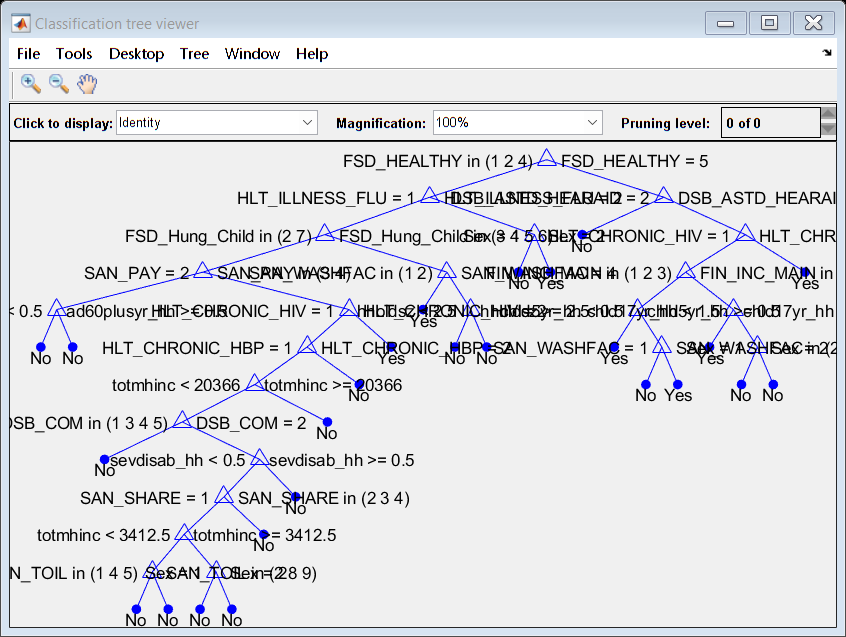

figure;
view(model.Trained{2}, 'Mode', 'graph');

% saveas(gcf, strcat(filepre, "decision_tree.png"));

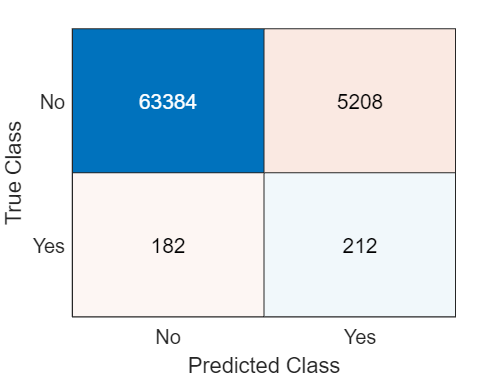

% Predict on the training set
predictedLabels = predict(model, Tog);
confusionchart(Tog.HLT_CHRONIC_TB, predictedLabels);
saveas(gcf, strcat(filepre, "confusion-matrix.png"));


% Compare with actual labels
cm = confusionmat(Tog.HLT_CHRONIC_TB, predictedLabels)

cm =        63384        5208
         182         212


tn = cm(1,1)

tn = 63384

fp = cm(1,2)

fp = 5208

fn = cm(2,1)

fn = 182

tp = cm(2,2)

tp = 212


accuracy = (tp+tn)/(tp+tn+fp+fn)

accuracy = 0.9219

precision = tp/(tp+fp)

precision = 0.0391

recall = tp/(tp+fn)

recall = 0.5381

f1score = 2*precision*recall/(precision+recall)

f1score = 0.0729

specificity = tn/(tn+fp)

specificity = 0.9241


statsTable = table(accuracy, precision, recall, specificity, f1score, ...
                   'VariableNames', {'Accuracy', 'Precision', 'Recall', 'Specificity', 'F1Score'});

disp(statsTable);

    Accuracy    Precision    Recall     Specificity    F1Score 
    ________    _________    _______    ___________    ________

    0.92187     0.039114     0.53807      0.92407      0.072927



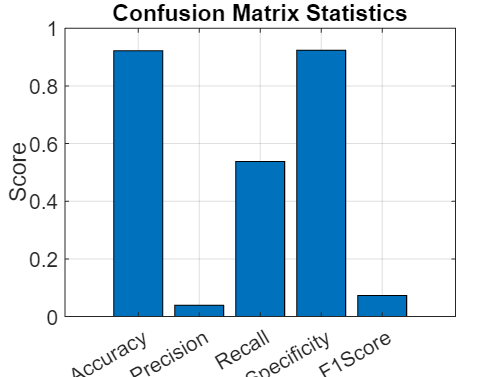


% Store metrics in a vector
metrics = [accuracy, precision, recall, specificity, f1score];
metricNames = {'Accuracy', 'Precision', 'Recall', 'Specificity', 'F1Score'};

% Create bar graph
figure;
bar(metrics);
set(gca, 'xticklabel', metricNames);
ylabel('Score');
title('Confusion Matrix Statistics');
ylim([0 1]);  % To keep the y-axis between 0 and 1
grid on;
saveas(gcf, strcat(filepre, "prediction-statistics.png"));

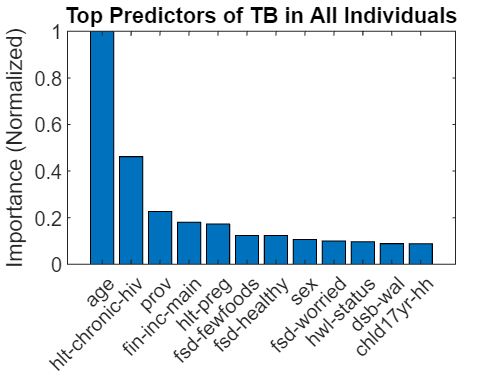

% Compute importance of each predictor
importance = predictorImportance(model);
importance = importance / max(importance);

% Plot feature importance
figure;
% Sort values descending
[sortedValues, sortIdx] = sort(importance, 'descend');
takeFirst = min(12,find(sortedValues == 0, 1, 'first') - 1);
sortedLabels = cellfun(@(s) lower(strrep(s, '_', '-')), predictorVars(sortIdx(1:takeFirst)), 'UniformOutput', false);

bar(sortedValues(1:takeFirst))
set(gca, 'XTickLabel', sortedLabels, 'XTickLabelRotation', 45)
ylabel('Importance (Normalized)')
title(strcat('Top Predictors of TB in All Individuals'));
saveas(gcf, strcat(filepre, "top-predictors.png"));